clc, clear, close all
datetime('now')

ans = datetime
   31-May-2023 17:06:38



addpath('C:\Users\emill\Desktop\IORN\L07');
load('constance.mat', 'hbar', 'm0', 'J2eV');

x = linspace(0.1e-9, 50e-9, 500);
dx = 0.1e-9;
dt = 0.02e-15;
lambda = 5e-9;
sigma = 5e-9;
U = 0;

Нормировка:

psi = exp(-((x - 15e-9) .^2 / (2 * sigma ^ 2)) + 1i * (2 * pi / lambda) .* x);
psi_norm = sqrt(sum(psi .* conj(psi)));

prl = real(psi) ./ psi_norm;
pim = imag(psi) ./ psi_norm;

ptot = prl + 1i * pim;
pnorm = sqrt(sum(ptot .* conj(ptot)))

pnorm = 1

Момент времени 0 фс:

PE = sum(ptot' * U .* ptot, "all");
H = diag(-2 * ones(1, numel(x))) + diag(ones(1, numel(x) - 1), 1) + diag(ones(1, numel(x) - 1), -1);
KE = real(sum(ptot'.* (-J2eV * ((hbar / dx) ^2 /(2 * m0)) * H) .* ptot, 'all'));
Etot = KE + PE;

subplot(3, 1, 1);
grid on;
hold on;

plot(x, prl, 'LineWidth', 2, "Color",'k');
plot(x, pim, 'LineStyle',":", "Color",'r','LineWidth', 2); 

xlabel ('x, meters', 'FontWeight', 'bold');
ylabel('\Re(\Psi) and \Im(\Psi)', 'FontWeight', 'bold');
legend ('\Re(\Psi)', '\Im(\Psi)');
subtitle(strjoin({'[KE PE Etot] = [', num2str(round(KE * 1e3)), ' ', num2str(round(PE * 1e3)), ' ', num2str(round(Etot * 1e3)), ']', ' meV'}), 'FontWeight', 'bold');
title('t = 0 fs', 'FontWeight', 'bold');

Момент времени 34 фс:

n = 2 : numel(x) - 1;
for t = 1 : 1700
    prl(n) = prl(n) - hbar * dt / (2 * m0 * dx ^ 2) .* (pim(n - 1) - 2 .* pim(n) + pim(n + 1));
    pim(n) = pim(n) + hbar * dt / (2 * m0 * dx ^ 2) .* (prl(n - 1) - 2 .* prl(n) + prl(n + 1));
end

ptot = prl + 1i * pim;

PE = mean(ptot' * U .* ptot, "all");
KE = real(sum(ptot' .* (-J2eV * ((hbar / dx) ^2 /(2 * m0)) * H) .* ptot, "all"));
Etot = KE + PE;

subplot(3, 1, 2);
grid on;
hold on;

plot(x, prl, 'LineWidth', 2, 'Color', 'k');
plot(x, pim, 'LineWidth', 2, 'Color','r','LineStyle',":");

xlabel ('x, meters', 'FontWeight', 'bold');
ylabel('\Re(\Psi) and \Im(\Psi)', 'FontWeight', 'bold');
subtitle(strjoin({'[KE PE Etot] = [', num2str(round(KE * 1e3)), ' ', num2str(round(PE * 1e3)), ' ', num2str(round(Etot * 1e3)), ']', ' meV'}), 'FontWeight', 'bold');
title('t = 34 fs', 'FontWeight', 'bold');

Момент времени 68 фс:

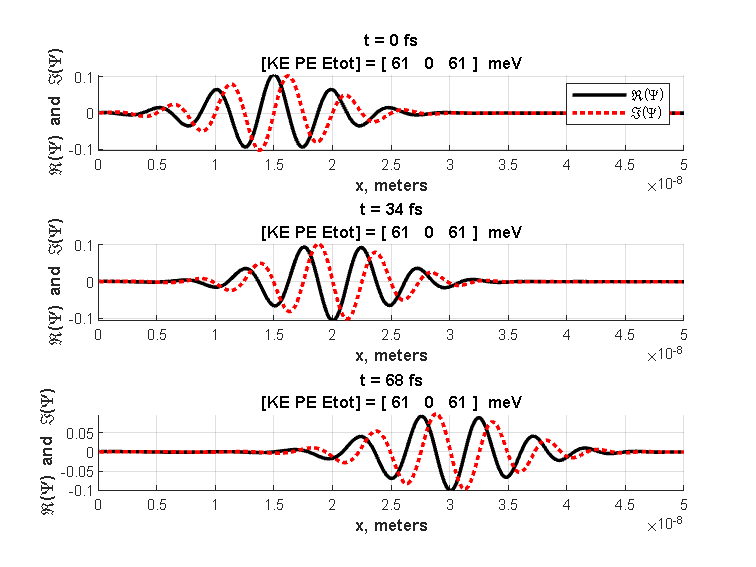

for t = 1 : 3400
    prl(n) = prl(n) - hbar * dt / (2 * m0 * dx ^ 2) .* (pim(n - 1) - 2 .* pim(n) + pim(n + 1));
    pim(n) = pim(n) + hbar * dt / (2 * m0 * dx ^ 2) .* (prl(n - 1) - 2 .* prl(n) + prl(n + 1));
end

ptot = prl + 1i * pim;

PE = mean(ptot' * U .* ptot, "all");
KE = real(sum(ptot' .* (-J2eV * ((hbar / dx) ^2 /(2 * m0)) * H) .* ptot, "all"));
Etot = KE + PE;

subplot(3, 1, 3);
grid on;
hold on;

plot(x, prl, 'LineWidth', 2, 'Color', 'k');
plot(x, pim, 'LineWidth', 2, 'Color','r','LineStyle',":");

xlabel ('x, meters', 'FontWeight', 'bold');
ylabel('\Re(\Psi) and \Im(\Psi)', 'FontWeight', 'bold');
subtitle(strjoin({'[KE PE Etot] = [', num2str(round(KE * 1e3)), ' ', num2str(round(PE * 1e3)), ' ', num2str(round(Etot * 1e3)), ']', ' meV'}), 'FontWeight', 'bold');
title('t = 68 fs', 'FontWeight', 'bold');


KE_ref_1 = hbar ^ 2 * J2eV / (2 * m0) * (2 * pi / lambda) ^ 2 * 1e3

KE_ref_1 = 60.1648

KE_ref_2 = m0 * (1e-8 / 68e-15) ^ 2 * J2eV / 2 * 1e3

KE_ref_2 = 61.4796